**Project 1: Numerical simulation of a model neuron**

Tasks:

1. Description of a neuron, numerical simulation of a model neuron: solving the system of differential equations using the Runge Kutta 4th order method, analyzing the correctness of choosing the time step.

2. Analyzing different regimes of a neuron dynamics, plotting time series and phase portraits of the signal, calculation of a regime map.

3. Adding Gaussian noise to the system, solving the system of differential equations with noise, analyzing the influence of noise amplitude on the system dynamics.

4. Adding the coupling between 2 neurons, analyzing synchronization between neurons for different values of the coupling strength.

5. Simulation of a neural network with global topology, analyzing the influence of external stimulus and noise amplitude by calculating characteristic correlation time.

f0=0;
t=1000;
dt=1;
fun=@function_0;

[f]=RungeKutta(t,dt,f0,[],fun)

f =      0     0
     1     0
     2    12
     3    36
     4    72
     5   120
     6   180
     7   252
     8   336
     9   432


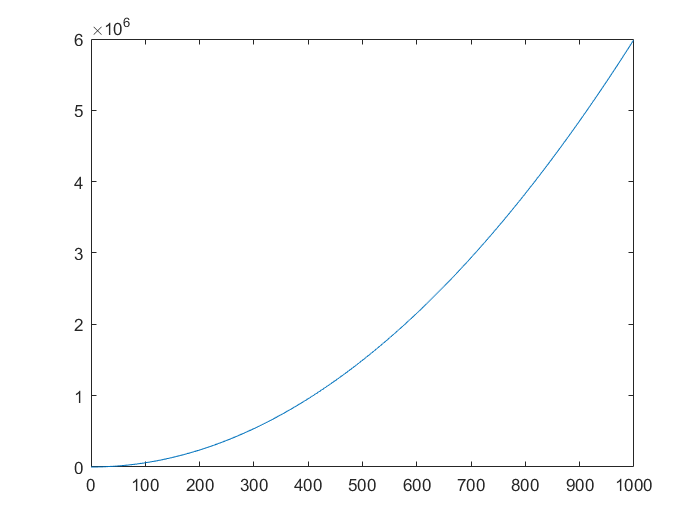

plot(f(:,1),f(:,2))

function fun = function_0(t,f,const)
    fun=f*2;
end